a0 = -0.7086;
b0 =  0.2406;
c0 = (a0+b0)/2;
epsilon = 0.05;
gamma = 0.001;
Nmax = 1000;
fprintf("%f, %f", a0,b0)

-0.708600, 0.240600

Znaleziono minimum x_min: -0.100312

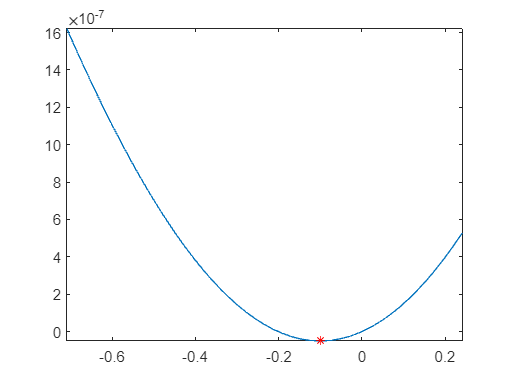

ans = lagrange(a0, b0, c0, @g, epsilon, gamma, Nmax);

a0 = -0.2750;
b0 =  0.0063;
c0 = (a0+b0)/2;
epsilon = 0.05;
gamma = 0.001;
Nmax = 1000;
fprintf("%f, %f", a0,b0)

-0.275000, 0.006300

Znaleziono minimum x_min: -0.100385

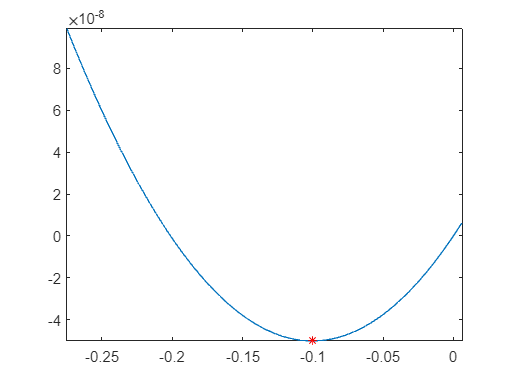

ans = lagrange(a0, b0, c0, @g, epsilon, gamma, Nmax);

a0 = 20.9746;
b0 =  37.1929;
c0 = (a0+b0)/2;
epsilon = 0.05;
gamma = 0.001;
Nmax = 1000;
fprintf("%f, %f", a0,b0)

20.974600, 37.192900

Znaleziono minimum x_min: 26.760156

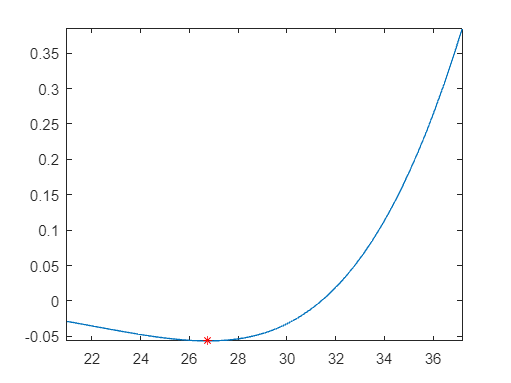

ans = lagrange(a0, b0, c0, @g, epsilon, gamma, Nmax);

a0 = -5.4371;
b0 =  -2.2335;
c0 = (a0+b0)/2;
epsilon = 0.05;
gamma = 0.001;
Nmax = 1000;
fprintf("%f, %f", a0,b0)

-5.437100, -2.233500

Znaleziono minimum x_min: -3.852435

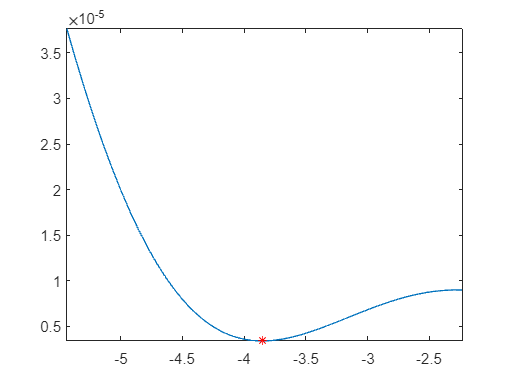

ans = lagrange(a0, b0, c0, @g, epsilon, gamma, Nmax);

function y = fun(x)
    y = 0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2;
end

function gi = g(x)
    px = [-10 -5 0 5 10];
    py = [0.0001 -0.1 0 0.1 -0.0001];
    stopien=5;
    W = polyfit(px, py, stopien);
    gi = (0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;
end

% przedzial <a,b>, i punkt c ktory nalezy do tego przedzialu
function x_ans = lagrange(a0, b0, c0, f, eps, gamma, N_max)
    i = 1;
    a(1) = a0;
    b(1) = b0;
    c(1) = c0;
    d(1) = 0;

    while 1
        num = f(a(i))*((c(i))^2 - (b(i))^2) + f(c(i))*((b(i))^2 - (a(i))^2) + f(b(i))*((a(i))^2 - (c(i))^2);
        den = f(a(i))*(c(i)-b(i)) + f(c(i))*(b(i)-a(i)) + f(b(i))*(a(i)-c(i));

        d(i) = 0.5 * (num/den);

        if a(i) < d(i) && d(i) < c(i)
            if f(d(i)) < f(c(i))
                a(i+1) = a(i);
                c(i+1) = d(i);
                b(i+1) = c(i);
            else
                a(i+1) = d(i);
                c(i+1) = c(i);
                b(i+1) = b(i);
            end
        else
            if c(i) < d(i) && d(i) < b(i)
                if f(d(i)) < f(c(i))
                    a(i+1) = c(i);
                    c(i+1) = d(i);
                    b(i+1) = b(i);
                else
                    a(i+1) = a(i);
                    c(i+1) = c(i);
                    b(i+1) = d(i);
                end
            else
                error("Algorytm nie jest zbiezny")
                return
            end
        end
        if i ~= 1
            if b(i) - a(i) < eps || abs(d(i) - d(i-1)) <= gamma
                x_ans = d(i);
                break
            end
        end
        x_ans = d(i);
        i = i + 1;
        
        if i > N_max
            error("Nie udalo sie osiagnac dokladnosci eps")
            return
        end

    end
    fprintf("Znaleziono minimum x_min: %f",x_ans)
    figure()
    fplot(f,[a0 b0])
    hold on
    plot( x_ans, f(x_ans),'r*')
    hold off
    return
end